# ROM Ph.D. Playground

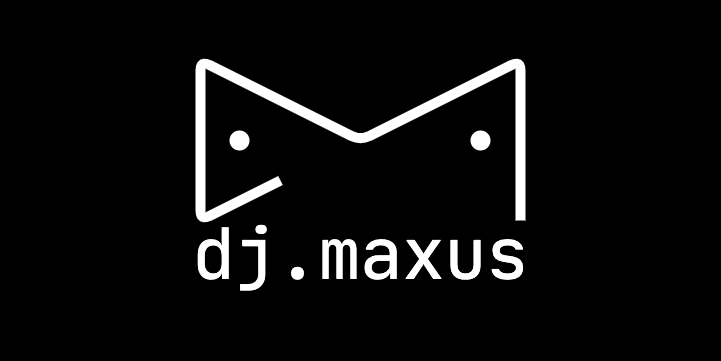

%% Analytical solution
% % generate linear matrix
% J = buildJacobian(zeros(Nx,2),1,problem.param);
% % u_t + Jx * u = q
% Jx = full([J.Jx,J.Jxb;zeros(2,Nx+2)]);
% % evaluate
% exact = problem.sol;
% X = calcGreenODE(Jx,[x0;bc.state(:,2)],problem.sol.t,-[problem.param.q.val;0;0]);
% exact.X = X(1:end-2,:);
% plotComp(exact, problem.sol, D, fig); fig;
%
% try DMDc
% X = exact.X;
% dX = diff(X,1,2)./dt;
% Q = repmat(-full(problem.param.q.val),1,Nt);
% [A,U,S] = dmds(X(:,2:end),dX-Q,23);
% dmded = problem.sol;
% dmded.X = calcGreenODE(-A,x0,problem.sol.t,-problem.param.q.val,23);
% dmded.X = real(dmded.X);
% plotComp(dmded, exact, D, fig); fig;

## Startup

startup;
clc;
close all;
fig = new_figure('Result');

## PDE Settings

- Dimensionality

Nx = 1000;

- Boundary Conditions

bc = genBC(1,[0,0]);

- Diffusion

k = 0;
model = @(u) [1+u^2*k,2*u*k];
D  = genDiffusion(Nx,0.9,1,0.5e-1,model);

- Initial Condition

x0 = genInit(Nx,0,2,0);

### Problem Constructors

- FOM

makeFOM = @(q,name) genProblem(name,Nx,genParam(D,bc,q),x0);

- ROM-I

makeROM_I = @(name,q,encoder) genProblem(name,Nx,genParam(D,bc,q),x0,encoder);

- ROM-II

makeROM_II = @(name,q,encoder,nfa) genProblem(name,Nx,genParam(D,bc,q),x0,encoder,nfa.res,nfa.jac);

## ODE settings

- Endtime $T$

T = 1;

- Number of timesteps $N_t$

Nt = 100;

- Timestep $\tau = \frac{T}{N_t}$

dt = T/Nt;

## Nonlinear  Solver Settings

- Convergence Criteria

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 1e-3,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 1e-3,...
    'tol_rel_g', 1e-3 ...
    );

- Newton solver

nlin_newton = @(x,Res,Jac) newton      (x,Res,Jac,newton_param);

- Newton — Gauss solver

nlin_gauss  = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param);

## Train set

q = genSource(Nx,0.6,1e+3);

## FOM

FOM = makeFOM(q,'FOM');
FOM = solveDif(T,Nt,FOM,nlin_newton);
plotSol(axes(figure),FOM);

## ROM

Collect Data

[X,W,Jf] = collectSolData(FOM);

### POD

Train Encoder

en_loss = 3;
en_loss = 10^(-en_loss);
en_crit = 1 - en_loss;
pod = PCA(X, en_crit, 'init', x0, 'sval_deg',1);

Elapsed time is 0.004211 seconds.


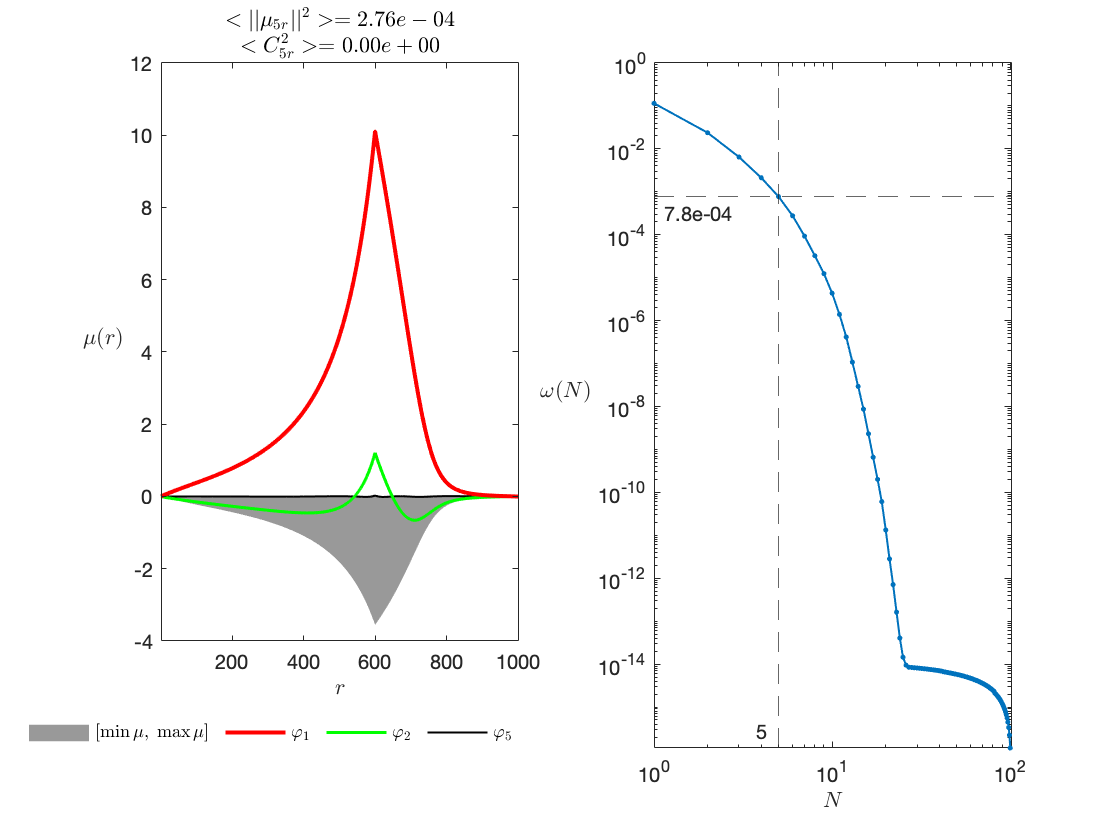

pod.plotSummary(figure);

### ROM-I

Perfom POD-ROM Calculation

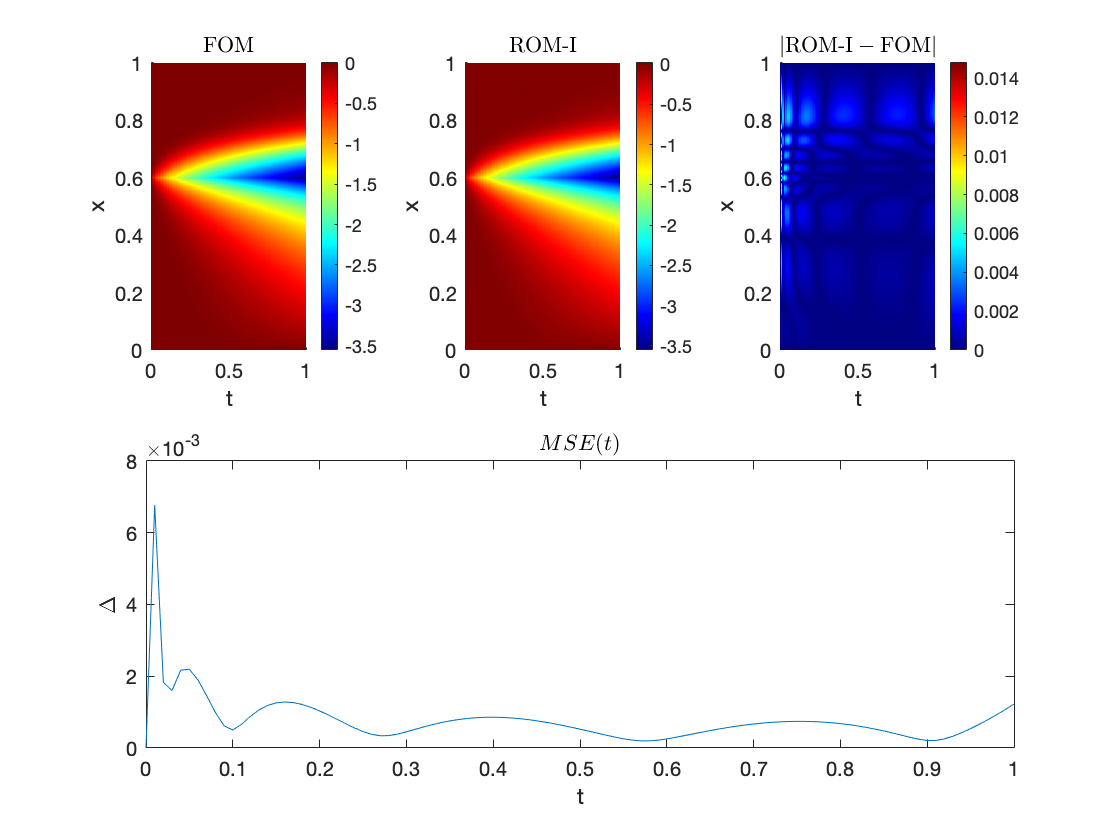

encoder = pod.genEncoder();

ROM.I = makeROM_I('ROM-I',q,encoder);
ROM.nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder.decjac);

ROM.I = solveDif(T,Nt,ROM.I,ROM.nlin);
ROM.I.X = encoder.decode(ROM.I.X);
plotComp(figure(),FOM,ROM.I);

## ROM-II

Collect data

[train.W,train.Jw] = collectNonlinData(train.FOM.sol);
% Make POD
N1 = floor(train.pod.npc() * 2);
train.gappy.R = PCA(train.W,N1,'init',zeros(Nx+1,1));
train.gappy.J = PCA(train.Jw,N1,'init',zeros(Nx+1,1));
% Set masks
N2 =floor(N1*2);
idx = unique([train.gappy.R.calcGreedy(N2),...
    train.gappy.J.calcGreedy(N2)]);

train.gappy.R = train.gappy.R.buildGappy(idx);
train.gappy.J = train.gappy.J.buildGappy(idx);

train.nfa.res = train.gappy.R.genNFA();
train.nfa.jac = train.gappy.J.genNFA();

train.ROM.II = makeROM_II('ROM-II',train.q,train.encoder,train.nfa);
train.ROM.II.sol = solveDif(T,Nt,train.ROM.II,train.ROM.nlin); % solve
train.ROM.II.sol.X = train.encoder.decode(train.ROM.II.sol.X); % decode solution
plotComp(fig,train.FOM.sol,train.ROM.II.sol);

## test set

test.q = genSource(Nx,0.55,1e+3);                       % specific property
% FOM
test.FOM = makeFOM(test.q,'test.FOM');          % setup
test.FOM.sol = solveDif(T,Nt,test.FOM,nlin_newton); % solve
plotComp(fig, train.FOM.sol, test.FOM.sol);                         % plot

## ROM-I

Encoder


test.pod = PCA(test.FOM.sol.X,0.99,'init',x0,'sval_deg',1);
test.encoder = test.pod.genEncoder();
% Problem
test.ROM.I = makeROM_I('test.ROM-I',test.q,test.encoder);
test.ROM.nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param,test.encoder.decjac);
% Solution
test.ROM.I.sol = solveDif(T,Nt,test.ROM.I,test.ROM.nlin); % solve
test.ROM.I.sol.X = test.encoder.decode(test.ROM.I.sol.X); % decode solution
plotComp(fig,test.FOM.sol,test.ROM.I.sol);                 % plot
% ROM-II

## Hypothesis

U1 = train.FOM.sol.X(:,2:end);
Phi1 = train.encoder.decjac(1);
C1 = U1 \ Phi1;

U2 = test.FOM.sol.X(:,2:end);
Phi2 = test.encoder.decjac(1);
C2 = U2 \ Phi2;

Phi3 = U2 * C1;
U3 = Phi3 * Phi3' * U2;

## ROM-I

Encoder

pod = PCA(U3,0.99,'init',x0,'sval_deg',1);
encoder = pod.genEncoder();
% Problem
ROM.I = makeROM_I('ROM-I',test.q,encoder);
ROM.nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder.decjac);
% Solution
ROM.I.sol = solveDif(T,Nt,ROM.I,ROM.nlin); % solve
ROM.I.sol.X = encoder.decode(ROM.I.sol.X); % decode solution
plotComp(fig,test.ROM.I.sol,ROM.I.sol);                 % plot

## Comparison

plotComp(fig,train.FOM.sol,test.FOM.sol);

## Collect ROM-II data

function [X,W,Jw] = collectSolData(sol)
    X = sol.X;
    W = [sol.nlin.residual];
    W = [W.W];
    Jw = [sol.nlin.jacobian];
    Jw = [Jw.Jf];
end